# Q1

clear
rng default
A = rand(3,5);
L = A>=0.5

L = 3×5 logical array
   1   1   0   1   1
   1   1   1   0   0
   0   0   1   1   1


ind = find(A>=0.5)

ind =      1
     2
     4
     5
     8
     9
    10
    12
    13
    15


# Q2

clear
x = -3*pi:pi/15:3*pi;
y = x;
[X,Y] = meshgrid(x,y);
warning off;
Z = sin(X).*sin(Y)./X./Y;

## (1)

num = length(find(isnan(Z)))

num = 181

## (2)

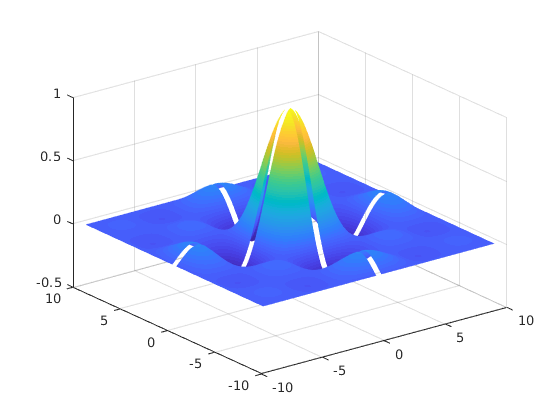

surf(X,Y,Z);
shading interp

## (3)

Lx = X==0;
Ly = Y==0;
X1 = X+Lx*realmin;
Y1 = Y+Ly*realmin;
Z1 = sin(X1).*sin(Y1)./X1./Y1;
num1 = length(find(isnan(Z1)))

num1 = 0

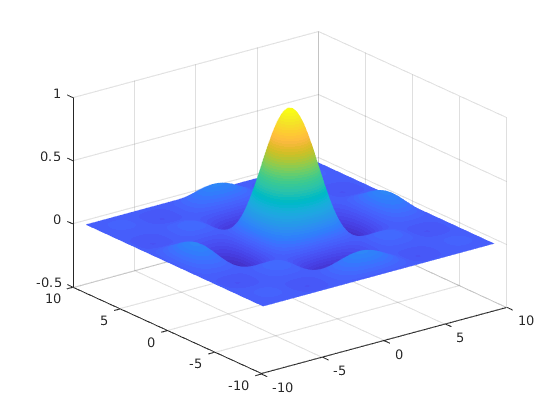

surf(X1,Y1,Z1);
shading interp

# Q3

clear
rng default
N = 1200;
A = rand(N);
b = rand(N,1);
tic
c = A\b;
toc

Elapsed time is 0.095590 seconds.



A1 = A; b1 = b;
tic
p = zeros(N,1); %存储第i列主元所在行编号
q = 1:N; %存储未处理过的行编号
a = zeros(N,1); %存储第i列主元
for j = 1:N
    [a(j),i_] = max(A1(N*(j-1)+q)); %选取主元，但编号不是矩阵行编号
    i = q(i_); p(j) = i; %得到真实的行编号
    mul = A1(:,j)/A1(i,j); mul(i) = 0;
    A1 = -mul*A1(i,:)+A1;
    b1 = -mul*b1(i)+b1;
    q(i_) = []; %把处理过的行编号从q中删除
end
b1 = b1(p); %把b和主元对齐
x = a.\b1;
toc

Elapsed time is 5.590586 seconds.



err1 = norm(x-c)

err1 = 2.6281e-11

b2 = A*x;
err2 = norm(b-b2)

err2 = 4.6725e-12

# Q4

## (1)

把F的列看做1000个向量的坐标，要找到6维列空间的一组基，扩充为500维空间的基$U$。这1000个向量在新基上的坐标 $F2=U^{-1}F$ 只有前6个维度有值。

为了找到 $U$，把 $F$ 看做线性变换，列空间即为像空间。

对F做奇异值分解：$F=USV^{-1}$，$U$ 是由像空间的基扩充而成，即为要找的一组基。


$$F_2=U^{-1}F=SV^{-1}$$


clear
load('W5Q4.mat');
[U,S,V] = svd(F);
F2 = S*V';
G = F2(1:6,:);

## (2)

第一步：从降维后的1000个向量中找到6个线性无关向量作为一组基

具体方法是从第2个到第1000个向量中随机取样，不选第1个向量的理由在第四步

B = G(:,1+unidrnd(999)); C = B;
for i = 2:6
    while(rank(C) ~= i)
        C = [B,G(:,1+unidrnd(999))];
    end
    B = C;
end

第二步：用得到的基作坐标变换

G2 = B\G;

第三步：把极小的元素化为0，其余化为1

G3 = abs(G2) > 1e-9;

第四步：把第1个向量归为1类，它在3个维度上坐标分量不为0（所以不能在第一步中作为基），找出这3个维度的编号。再把其余在这个三个维度上坐标分量至少一个不为0的向量归为1类

k = find(G3(:,1));
ind = logical(sum(G3(k,:)));
rank1 = rank(F(:,ind),1e-9)

rank1 = 3

rank0 = rank(F(:,~ind),1e-9)

rank0 = 3